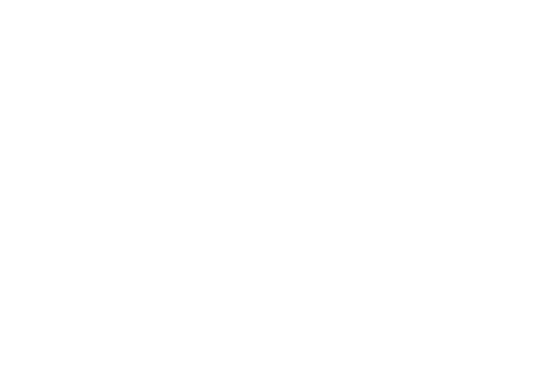

%provem de fer HOG amb una imatge
h = [-1 0 1];
h2 = [-1;0;1];

I = imread('BioID_0003.pgm');

%ndg = double(rgb2gray(I));
ndg = double(I);
imshow(ndg);

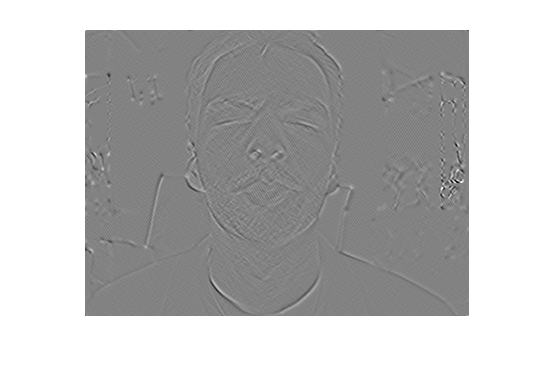

H = imfilter(ndg,h); %contorns horitzontals
VH = imfilter(H,h2); %contorns verticals
imshow(VH,[]);

%convert gradients to angles(deg)
GV = atand(VH);
%make gradients be between 0 180 by adding 180 to negs
GV = mod(GV,180);

[F, C] = size(GV);
cellH = floor(F/9);cellW = floor(C/9);
HOGs = cell(9,9); % matrix of histos of bins of pixels
for i = 1:9
    for j = 1:9
        HOGs{i,j} = zeros(1,9); %bins of 20 deg ranges
    end
end
%calculate vale of each cell: histogram of gradients of pixels
for i = 1:9
    for j = 1:9
        s = 0;
        for k = 1:cellH
            for m = 1:cellW
                %count value of gradient into histogram of cell
                deg =GV(k+(i-1)*cellH,m+(j-1)*cellW);
                %decide contribution to bins of deg
                %bins are 10 30 50 70 90 ....
                offset = mod(deg,20) - 10;
                %contributions to adjacent bins
                %one must always be 0
                bin = ceil(deg/20);
                if(bin==0)
                    bin = 1;
                end
                [left,right,center]=binContribs(offset);
                if(bin == 1)
                    HOGs{i,j}(9) = HOGs{i,j}(9) + left*deg;
                    HOGs{i,j}(bin) = HOGs{i,j}(bin) + center*deg;
                    HOGs{i,j}(bin+1) = HOGs{i,j}(bin+1) + right*deg;
                elseif(bin == 9)
                    HOGs{i,j}(bin-1) = HOGs{i,j}(bin-1) + left*deg;
                    HOGs{i,j}(bin) = HOGs{i,j}(bin) + center*deg;
                    HOGs{i,j}(1) = HOGs{i,j}(1) + right*deg;
                else
                    HOGs{i,j}(bin-1) = HOGs{i,j}(bin-1) + left*deg;
                    HOGs{i,j}(bin) = HOGs{i,j}(bin) + center*deg;
                    HOGs{i,j}(bin+1) = HOGs{i,j}(bin+1) + right*deg;
                end
            end
        end
    end
end

Subscript indices must either be real positive integers or logicals.